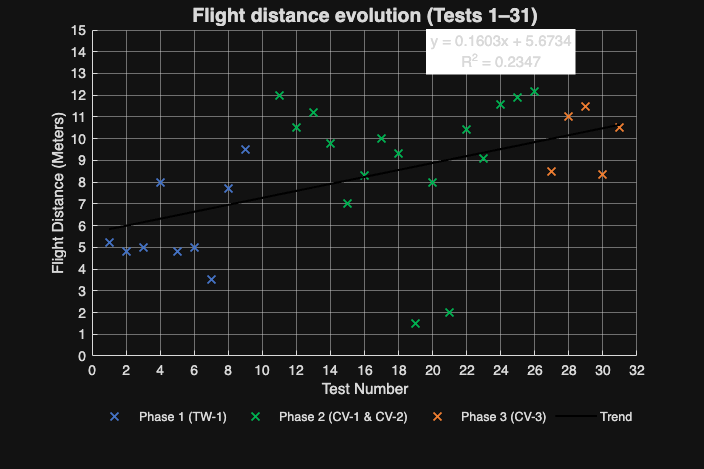

% Glider Flight Data
%var setup
test_num = 1:31;
distance = [5.2, 4.8, 5.0, 8.0, 4.8, 5.0, 3.5, 7.7, 9.5, NaN, ...
            12.0, 10.5, 11.2, 9.8, 7.0, 8.3, 10.0, 9.33, 1.5, 8.0, ...
            2.0, 10.4, 9.11, 11.55, 11.9, 12.16, 8.5, 11.0, 11.48, 8.36, 10.52];

phase1_idx = 1:9;    % TW-1
phase2_idx = 11:26;  % CV-1 & CV-2
phase3_idx = 27:31;  % CV-3

% plot
figure('Position', [100, 100, 900, 600]);
hold on;

p1 = plot(test_num(phase1_idx), distance(phase1_idx), 'x', 'MarkerSize', 8, 'LineWidth', 1.5, 'Color', '#4472C4'); 
p2 = plot(test_num(phase2_idx), distance(phase2_idx), 'x', 'MarkerSize', 8, 'LineWidth', 1.5, 'Color', '#00B050'); 
p3 = plot(test_num(phase3_idx), distance(phase3_idx), 'x', 'MarkerSize', 8, 'LineWidth', 1.5, 'Color', '#ED7D31'); 

% trendline calc
valid_idx = ~isnan(distance);
x_valid = test_num(valid_idx);
y_valid = distance(valid_idx);

% make slope
coeffs = polyfit(x_valid, y_valid, 1);
y_fit = polyval(coeffs, test_num);

% Plottlabing
p4 = plot(test_num, y_fit, 'k-', 'LineWidth', 1.5);


y_mean = mean(y_valid);
SStot = sum((y_valid - y_mean).^2);
SSres = sum((y_valid - polyval(coeffs, x_valid)).^2);
Rsq = 1 - (SSres / SStot);

% Formatlabing
title('Flight distance evolution (Tests 1–31)', 'FontSize', 14);
xlabel('Test Number', 'FontSize', 11);
ylabel('Flight Distance (Meters)', 'FontSize', 11);
xlim([0 32]);
ylim([0 15]);
xticks(0:2:32);
yticks(0:1:15);
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8], 'GridAlpha', 0.5);
lgd = legend([p1, p2, p3, p4], {'Phase 1 (TW-1)', 'Phase 2 (CV-1 & CV-2)', 'Phase 3 (CV-3)', 'Trend'}, ...
    'Location', 'southoutside', 'Orientation', 'horizontal');
lgd.Box = 'off';
eq_str = sprintf('y = %.4fx + %.4f\nR^2 = %.4f', coeffs(1), coeffs(2), Rsq);
text(24, 14, eq_str, 'FontSize', 11, 'HorizontalAlignment', 'center', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none', 'Margin', 2);


hold off;